# TVGMD

close all
clear
clc
data = readmatrix('sub-02_Sherlock_Mov_DMN_AVG_112_tmseries.xlsx');


%T considered as number of data points analyzed, f as number of brain
%regions
T =943; t = (1:T)/T; Const=0;
f = data-mean(data,1);
f = f';

Z = gsp_distanz(f').^2;
% we can multiply the pairwise distances with a number to control sparsity
[W] = gsp_learn_graph_log_degrees(Z, 1, 5);

# iters: 1000. Rel primal: 5.0144e-04 Rel dual: 5.0138e-04  OBJ 3.328e+01
Time needed is 0.038217 seconds


% clean up zeros
W(W<1e-5) = 0;
G = gsp_graph(W);


% Running TVGMD:
norm_input=f/max(max(f));
[imf, L_out] = TGMD(norm_input, 2000, 1, 0.5, 9, G.L, 1, 1e-7)

# iters:  500. Rel primal: 9.9551e-03 Rel dual: 7.8744e-04  OBJ 2.450e+01
Time needed is 0.018547 seconds
# iters:  162. Rel primal: 8.9805e-06 Rel dual: 8.5202e-07  OBJ 9.773e+00
Time needed is 0.006160 seconds
# iters:  126. Rel primal: 9.9828e-06 Rel dual: 1.3632e-06  OBJ 5.946e+00
Time needed is 0.004347 seconds
# iters:   88. Rel primal: 8.6390e-06 Rel dual: 7.2014e-06  OBJ 3.802e+00
Time needed is 0.003296 seconds
# iters:   82. Rel primal: 9.9620e-06 Rel dual: 3.2791e-06  OBJ 2.329e+00
Time needed is 0.002924 seconds
# iters:   75. Rel primal: 9.0439e-06 Rel dual: 9.2650e-06  OBJ 2.788e+00
Time needed is 0.002475 seconds
# iters:   91. Rel primal: 8.3751e-06 Rel dual: 4.0023e-06  OBJ 3.590e+00
Time needed is 0.003019 seconds
# iters:  101. Rel primal: 9.0042e-06 Rel dual: 2.1670e-06  OBJ 4.086e+00
Time needed is 0.003373 seconds
# iters:  106. Rel primal: 8.7727e-06 Rel dual: 6.5895e-07  OBJ 4.417e+00
Time needed is 0.003457 seconds
# iters:  500. Rel primal: 4.6772e-05 Rel dual

imf = imf(:,:,1) =

    0.0916    0.1317    0.1673    0.2382    0.0986    0.1225    0.0919    0.1206    0.1090    0.1050    0.1469    0.1647    0.1208    0.0660    0.0191    0.0685    0.1222    0.1937    0.0914    0.0572    0.0688    0.0337    0.0910    0.0485    0.1047    0.1102    0.1148    0.0525   -0.0016    0.0010    0.0814    0.1231    0.1109    0.0056    0.0285   -0.0122    0.0311    0.0523    0.0239    0.0791    0.0711    0.0392   -0.0321   -0.0302    0.0084    0.0993    0.0791    0.0701   -0.0196   -0.0085    0.0077    0.0408    0.0116    0.0378    0.0520    0.0374   -0.0331   -0.0394   -0.0276    0.0441    0.0763    0.0628   -0.0385   -0.0506   -0.0091    0.0037    0.0086    0.0132    0.0336   -0.0035    0.0071   -0.0737   -0.0459   -0.0045    0.0389    0.0971   -0.0496   -0.0360   -0.0171   -0.0298    0.0541    0.0308    0.0276    0.0365    0.0076    0.0138   -0.0589    0.0384    0.0652    0.1244    0.0317    0.0226    0.0360   -0.0145    0.1303    0.0741    0.0653    0.0911

L_out = L_out(:,:,1) =

         0    0.0031    0.0015    0.0031    0.0015
    0.0031         0    0.0015    0.0031    0.0015
    0.0015    0.0015         0    0.0015    0.9109
    0.0031    0.0031    0.0015         0    0.0015
    0.0015    0.0015    0.9109    0.0015         0


L_out(:,:,2) =

         0         0    1.2526         0         0
         0         0         0    0.9639         0
    1.2526         0         0         0         0
         0    0.9639         0         0    0.6488
         0         0         0    0.6488         0


L_out(:,:,3) =

         0         0         0    1.0325         0
         0         0    0.9764         0         0
         0    0.9764         0         0    0.4621
    1.0325         0         0         0         0
         0         0    0.4621         0         0


L_out(:,:,4) =

         0         0    0.6555         0    0.7457
         0         0         0    1.0117         0
    0.6555         0         0         0    0.9438
    

%for i = 1:8
%    figure;
%    plot(t(:,25:T-25)*(T-1), f(i,25:T-25))
%    title("figure " + i)
%end


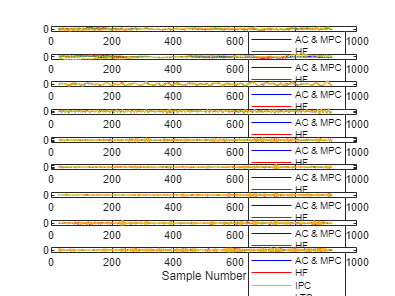

% Test between two channels:

c1 = 1;
c2 = 2;
c3 = 3;
c4 = 4;
c5 = 5;
c6 = 4;
c7 = 4;
c8 = 4;
c9 = 4;
c10 = 4;

figure;
%subplot(611); plot(T*t(:,25:T-25), f(c1, 25:T-25), "blue", T*t(:,25:T-25), f(c2, 25:T-25), 'red') 
%subplot(612); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 1), "blue", T*t(:,25:T-25), imf(c2, 25:(T-25), 1), 'red')
%subplot(613); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 2), "blue", T*t(:,25:T-25), imf(c2, 25:(T-25), 2), 'red')
%subplot(614); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 3), "blue", T*t(:,25:T-25), imf(c2, 25:(T-25), 3), 'red')
%subplot(615); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 4), "blue", T*t(:,25:T-25), imf(c2, 25:(T-25), 4), 'red')
%subplot(616); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 5), "blue", T*t(:,25:T-25), imf(c2, 25:(T-25), 5), 'red')

subplot(911); plot(T*t(:,25:T-25), f(c1, 25:T-25), "blue", T*t(:,25:T-25), f(c2, 25:T-25), 'red', T*t(:,25:T-25), f(c3, 25:T-25),T*t(:,25:T-25), f(c4, 25:T-25),T*t(:,25:T-25), f(c5, 25:T-25),T*t(:,25:T-25), f(c6, 25:T-25),T*t(:,25:T-25), f(c7, 25:T-25),T*t(:,25:T-25), f(c8, 25:T-25),T*t(:,25:T-25), f(c9, 25:T-25),T*t(:,25:T-25), f(c10, 25:T-25)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC') % original
subplot(912); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 1), "blue", T*t(:,25:T-25), imf(c2, 25:(T-25), 1), 'red',T*t(:,25:T-25), imf(c3, 25:T-25, 1),T*t(:,25:T-25), imf(c4, 25:T-25, 1),T*t(:,25:T-25), imf(c5, 25:T-25, 1),T*t(:,25:T-25), imf(c6, 25:T-25, 1),T*t(:,25:T-25), imf(c7, 25:T-25, 1),T*t(:,25:T-25), imf(c8, 25:T-25, 1),T*t(:,25:T-25), imf(c9, 25:T-25, 1),T*t(:,25:T-25), imf(c10, 25:T-25, 1)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC') % weekly
subplot(913); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 2), "blue", T*t(:,25:T-25), imf(c2, 25:(T-25), 2), 'red',T*t(:,25:T-25), imf(c3, 25:T-25, 2),T*t(:,25:T-25), imf(c4, 25:T-25, 2),T*t(:,25:T-25), imf(c5, 25:T-25, 2),T*t(:,25:T-25), imf(c6, 25:T-25, 2),T*t(:,25:T-25), imf(c7, 25:T-25, 2),T*t(:,25:T-25), imf(c8, 25:T-25, 2),T*t(:,25:T-25), imf(c9, 25:T-25, 2),T*t(:,25:T-25), imf(c10, 25:T-25, 2)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC') % 24 hourly/daily electricity consumption patterns
subplot(914); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 3), "blue", T*t(:,25:T-25), imf(c2, 25:T-25, 3), 'red',T*t(:,25:T-25), imf(c3, 25:T-25, 3),T*t(:,25:T-25), imf(c4, 25:T-25, 3),T*t(:,25:T-25), imf(c5, 25:T-25, 3),T*t(:,25:T-25), imf(c6, 25:T-25, 3),T*t(:,25:T-25), imf(c7, 25:T-25, 3),T*t(:,25:T-25), imf(c8, 25:T-25, 3),T*t(:,25:T-25), imf(c9, 25:T-25, 3),T*t(:,25:T-25), imf(c10, 25:T-25, 3)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(915); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 4), "blue", T*t(:,25:T-25), imf(c2, 25:T-25, 4), 'red',T*t(:,25:T-25), imf(c3, 25:T-25, 4),T*t(:,25:T-25), imf(c4, 25:T-25, 4),T*t(:,25:T-25), imf(c5, 25:T-25, 4),T*t(:,25:T-25), imf(c6, 25:T-25, 4),T*t(:,25:T-25), imf(c7, 25:T-25, 4),T*t(:,25:T-25), imf(c8, 25:T-25, 4),T*t(:,25:T-25), imf(c9, 25:T-25, 4),T*t(:,25:T-25), imf(c10, 25:T-25, 4)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(916); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 5), "blue", T*t(:,25:T-25), imf(c2, 25:T-25, 5), 'red',T*t(:,25:T-25), imf(c3, 25:T-25, 5),T*t(:,25:T-25), imf(c4, 25:T-25, 5),T*t(:,25:T-25), imf(c5, 25:T-25, 5),T*t(:,25:T-25), imf(c6, 25:T-25, 5),T*t(:,25:T-25), imf(c7, 25:T-25, 5),T*t(:,25:T-25), imf(c8, 25:T-25, 5),T*t(:,25:T-25), imf(c9, 25:T-25, 5),T*t(:,25:T-25), imf(c10, 25:T-25, 5)),ylabel('Amplitude'), legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(917); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 6), "blue", T*t(:,25:T-25), imf(c2, 25:T-25, 6), 'red',T*t(:,25:T-25), imf(c3, 25:T-25, 6),T*t(:,25:T-25), imf(c4, 25:T-25, 6),T*t(:,25:T-25), imf(c5, 25:T-25, 6),T*t(:,25:T-25), imf(c6, 25:T-25, 6),T*t(:,25:T-25), imf(c7, 25:T-25, 6),T*t(:,25:T-25), imf(c8, 25:T-25, 6),T*t(:,25:T-25), imf(c9, 25:T-25, 6),T*t(:,25:T-25), imf(c10, 25:T-25, 6)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(918); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 7), "blue", T*t(:,25:T-25), imf(c2, 25:T-25, 7), 'red',T*t(:,25:T-25), imf(c3, 25:T-25, 7),T*t(:,25:T-25), imf(c4, 25:T-25, 7),T*t(:,25:T-25), imf(c5, 25:T-25, 7),T*t(:,25:T-25), imf(c6, 25:T-25, 7),T*t(:,25:T-25), imf(c7, 25:T-25, 7),T*t(:,25:T-25), imf(c8, 25:T-25, 7),T*t(:,25:T-25), imf(c9, 25:T-25, 7),T*t(:,25:T-25), imf(c10, 25:T-25, 7)),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC')
subplot(919); plot(T*t(:,25:T-25), imf(c1, 25:T-25, 8), "blue", T*t(:,25:T-25), imf(c2, 25:T-25, 8), 'red',T*t(:,25:T-25), imf(c3, 25:T-25, 8),T*t(:,25:T-25), imf(c4, 25:T-25, 8),T*t(:,25:T-25), imf(c5, 25:T-25, 8),T*t(:,25:T-25), imf(c6, 25:T-25, 8),T*t(:,25:T-25), imf(c7, 25:T-25, 8),T*t(:,25:T-25), imf(c8, 25:T-25, 8),T*t(:,25:T-25), imf(c9, 25:T-25, 8),T*t(:,25:T-25), imf(c10, 25:T-25, 8)),xlabel('Sample Number'),legend('AC & MPC', 'HF', 'IPC', 'LTC', 'PCC'),

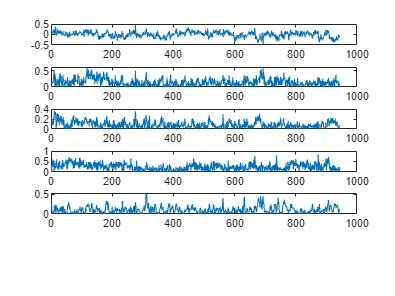

% Comparison of the imfs to the original signal

figure; 
subplot(611);plot(sum(imf(1,:,:),3))
subplot(612);plot(abs(f(2, :)-sum(imf(2,:,:),3)))
subplot(613);plot(abs(f(3, :)-sum(imf(3,:,:),3)))
subplot(614);plot(abs(f(4, :)-sum(imf(4,:,:),3)))
subplot(615);plot(abs(f(5, :)-sum(imf(5,:,:),3)))

%subplot(616);plot(abs(f(6, :)-sum(imf(6,:,:),3)))


% Plot graphs

% find energy of each Mode
e1=sqrt(sum(imf(:,:,1).^2,2));
e2=sqrt(sum(imf(:,:,2).^2,2));
e3=sqrt(sum(imf(:,:,3).^2,2));
e4=sqrt(sum(imf(:,:,4).^2,2));
e5=sqrt(sum(imf(:,:,5).^2,2));
e6=sqrt(sum(imf(:,:,6).^2,2));
e7=sqrt(sum(imf(:,:,7).^2,2));
e8=sqrt(sum(imf(:,:,8).^2,2));
e9=sqrt(sum(imf(:,:,9).^2,2));
e10=sqrt(sum(imf(:,:,10).^2,2));

Index in position 3 exceeds array bounds. Index must not exceed 9.

%e11=sqrt(sum(imf(:,:,11).^2,2));
%e12=sqrt(sum(imf(:,:,12).^2,2));
%e13=sqrt(sum(imf(:,:,13).^2,2));
%e14=sqrt(sum(imf(:,:,14).^2,2));
%e15=sqrt(sum(imf(:,:,15).^2,2));



% figure
figure('Position',[489, 343, 714, 420])

%Number of labels
%nLabels = uint32(1):uint32(5);
%nLabels = {'n1','n2','n3','n4','n5','n6','n7','n8','n9','n10','n11','n12','n13','n14','n15','n16','n17','n18','n19','n20','n21','n22','n23','n24','n25','n26','n27','n28','n29','n30','n31','n32','n33','n34','n35','n36','n37','n38','n39','n40','n41','n42','n43','n44','n45','n46','n47','n48','n49','n50',} ;
%nLabels = {'Anterior cingulate and medial prefrontal cortex','Hippocampal formation','Inferior parietal cortex','Lateral Temporal cortex','Posterior cingulate cortex'};
nLabels = {'AC & MPC', 'HF', 'IPC', 'LTC', 'PCC'};
L_out(L_out<0.001)=0;


g=graph(L_out(:,:,1));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,1,'Position',[0.05,0.55,0.45,0.35]); s1=plot(g,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
g.Nodes.NodeColors = e1;
s1.NodeCData = g.Nodes.NodeColors;
colormap(jet); caxis auto
colorbar
title('IMF 1 Connectivity','FontSize',14)

g=graph(L_out(:,:,2));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,2,'Position',[0.525,0.55,0.45,0.35]); s2=plot(g,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
g.Nodes.NodeColors = e2;
s2.NodeCData = g.Nodes.NodeColors;
colormap(jet); caxis auto
colorbar
title('IMF 2 Connectivity','FontSize',14)

g=graph(L_out(:,:,3));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,3,'Position',[0.05,0.1,0.45,0.35]); s3=plot(g,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
g.Nodes.NodeColors = e3;
s3.NodeCData = g.Nodes.NodeColors;
colormap(jet); caxis auto
colorbar
title('IMF 3 Connectivity','FontSize',14)

g=graph(L_out(:,:,4));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,4,'Position',[0.525,0.1,0.45,0.35]);s4=plot(g,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
g.Nodes.NodeColors = e4;
s4.NodeCData = g.Nodes.NodeColors;
colormap(jet); caxis auto 
colorbar
title('IMF 4 Connectivity','FontSize',14)


% L = [1 0 -1 0; 0 1 0 -1; -1 0 1 0; 0 -1 0 -1];
% imf = TV_GMD(f, 2000, 100, 0, 3, L, 0, 1e-7);

% u=imf;
% figure; subplot(211); plot(u(1,:,1)); hold on; plot(u(2,:,1)); hold on; plot(u(3,:,1)); hold on; plot(u(4,:,1)); ylim([-5,5])    
% subplot(212); plot(u(1,:,2)); hold on; plot(u(2,:,2)); hold on; plot(u(3,:,2)); hold on; plot(u(4,:,2)); ylim([-5,5]) 

figure('Position',[489, 343, 714, 420])

%Number of labels
%nLabels = uint32(1):uint32(5);
%nLabels = {'n1','n2','n3','n4','n5','n6','n7','n8','n9','n10','n11','n12','n13','n14','n15','n16','n17','n18','n19','n20','n21','n22','n23','n24','n25','n26','n27','n28','n29','n30','n31','n32','n33','n34','n35','n36','n37','n38','n39','n40','n41','n42','n43','n44','n45','n46','n47','n48','n49','n50',} ;
%nLabels = {'Anterior cingulate and medial prefrontal cortex','Hippocampal formation','Inferior parietal cortex','Lateral Temporal cortex','Posterior cingulate cortex'};
nLabels = {'AC & MPC', 'HF', 'IPC', 'LTC', 'PCC'};
L_out(L_out<0.001)=0;

g=graph(L_out(:,:,2));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,1,'Position',[0.05,0.55,0.45,0.35]); s1=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s1.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 1 IMF 2 Connectivity','FontSize',14)

g=graph(L_out(:,:,3));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,2,'Position',[0.525,0.55,0.45,0.35]); s2=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s2.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 1 IMF 3 Connectivity','FontSize',14)

g=graph(L_out(:,:,4));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,3,'Position',[0.05,0.1,0.45,0.35]); s3=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s3.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 1 IMF 4 Connectivity','FontSize',14)

g=graph(L_out(:,:,5));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,4,'Position',[0.525,0.1,0.45,0.35]); s4=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s4.EdgeCData = g.Edges.EdgeColors;
colormap(jet); clim ([0 1])
colorbar
title('Subject 1 IMF 5 Connectivity','FontSize',14)

nLabels = {'AC & MPC', 'HF', 'IPC', 'LTC', 'PCC'};
g=graph(L_out(:,:,2));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,1,'Position',[0.05,0.55,0.45,0.35]); s1=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s1.EdgeCData = g.Edges.EdgeColors;
colormap(jet); caxis auto
colorbar
title('c_2 Connectivity','FontSize',14)

g=graph(L_out(:,:,3));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,2,'Position',[0.525,0.55,0.45,0.35]); s2=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s2.EdgeCData = g.Edges.EdgeColors;
colormap(jet); caxis auto
colorbar
title('c_3 Connectivity','FontSize',14)

g=graph(L_out(:,:,4));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,3,'Position',[0.05,0.1,0.45,0.35]); s3=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s3.EdgeCData = g.Edges.EdgeColors;
colormap(jet); caxis auto
colorbar
title('c_4 Connectivity','FontSize',14)

g=graph(L_out(:,:,5));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);
subplot(2,2,4,'Position',[0.525,0.1,0.45,0.35]);s4=plot(g,'EdgeLabel', g.Edges.Weight,'layout','circle','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({});
edge_strength = g.Edges.Weight;
g.Edges.EdgeColors = edge_strength/max(edge_strength);
s4.EdgeCData = g.Edges.EdgeColors;
colormap(jet); caxis auto
colorbar
title('c_5 Connectivity','FontSize',14)

% figure with distance between each person 
figure('Position',[489, 343, 714, 470])

%nLabels = uint32(1):uint32(5);
nLabels = {'Anterior cingulate and medial prefrontal cortex','Hippocampal formation','Inferior parietal cortex','Lateral Temporal cortex','Posterior cingulate cortex'};
L_out(L_out<0.001)=0;

g = graph(L_out(:,:,2));
LWidths = 5*g.Edges.Weight/max(g.Edges.Weight);

% Plot the graph and get the plot object
subplot(2,2,1,'Position',[0.1,0.3,0.9,0.6]);s1=plot(g,'layout','force','LineWidth',LWidths,'NodeLabel',nLabels,'NodeFontSize', 14); xticklabels({}); yticklabels({}); 
xticklabels({});
yticklabels({});

% Set the node colors based on e1
g.Nodes.NodeColors = e2;
s1.NodeCData = g.Nodes.NodeColors;

colormap(jet); 
caxis auto
colorbar
title('c_2 Connectivity','FontSize',14)
SampleRate = 0.67;
[pxx,f] = pwelch(imf(:,:,2)',500,0,1024,SampleRate);
subplot('Position',[0.1 0.1 .85 .18]); box on; plot(f,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 100])

SampleRate = 0.67;
L = 4;
for X = 1:L
[pxx,f] = pwelch(imf(:,:,X)',500,0,1024,SampleRate);
subplot(4,1,X),plot(f,10*log10(pxx)); xlabel('Freq (Hz)','FontSize',9); ylabel('dB/Hz','FontSize',9);xlim([0 0.25])
title(['IMF ', num2str(X)])
end